# Pole-Zero Analysis

 This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output Inline`.

## Transfer function representation of a DC motor

Another essential electric vehicle (EV) component is the DC motor. 

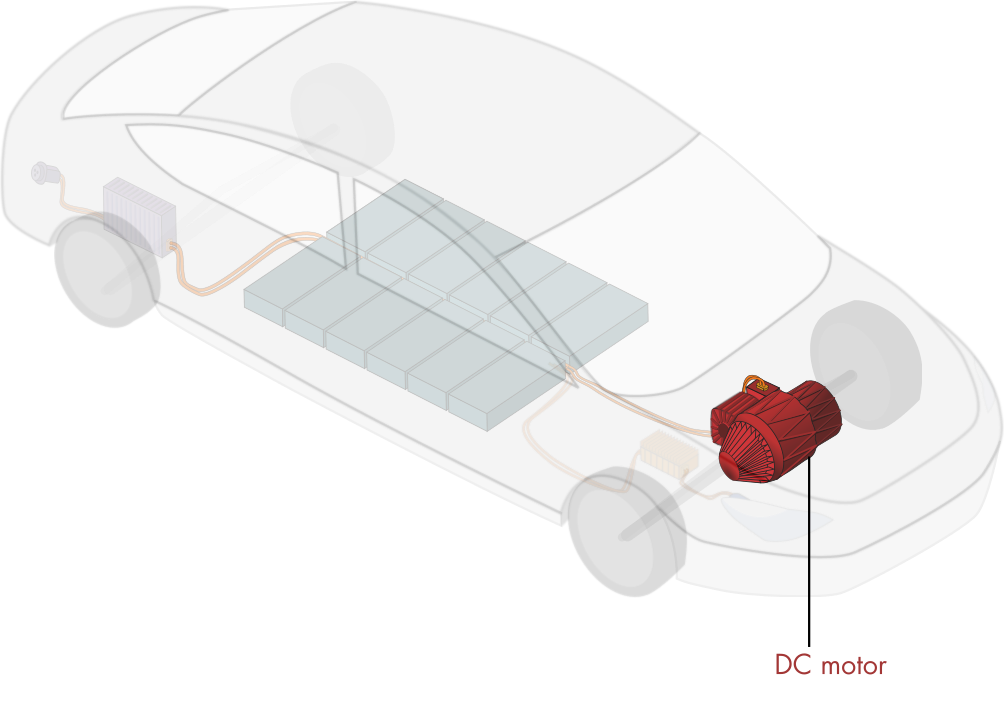

*Simplified EV schematic*

The purpose of the DC motor is to convert electrical energy to mechanical. The mechanical energy is manifested as a torque on the drive shaft. This torque is converted to a traction force by the wheels, which causes the vehicle to move.

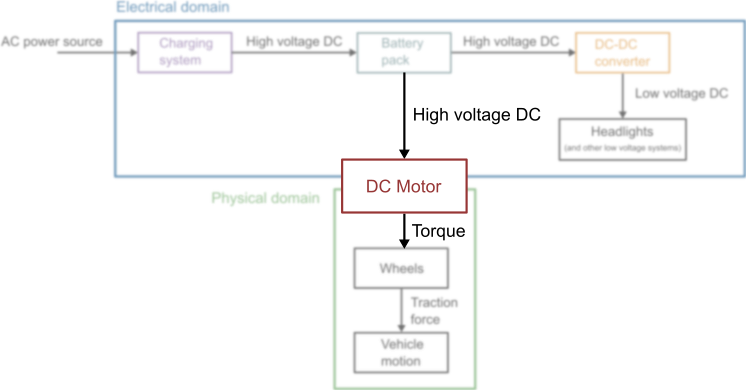

*The DC motor bridges the electrical and physical domains.*

A DC motor works by conducting a current through an armature that can rotate freely. The fixed brushes transmit the current to the rotating commutators. The current flowing through the armature passes through a magnetic field generated by the stator magnets, resulting in a Lorentz force in the perpendicular direction ($\mathbf{F} = i\mathbf{\ell} \times \mathbf{B}$, where $\mathbf{\ell}$ points in the wire direction). The two sides of the armature each produce a force, resulting in a net torque on the rotor $T$. If sufficient torque is applied, the shaft rotates, changing the angular position $\theta$.

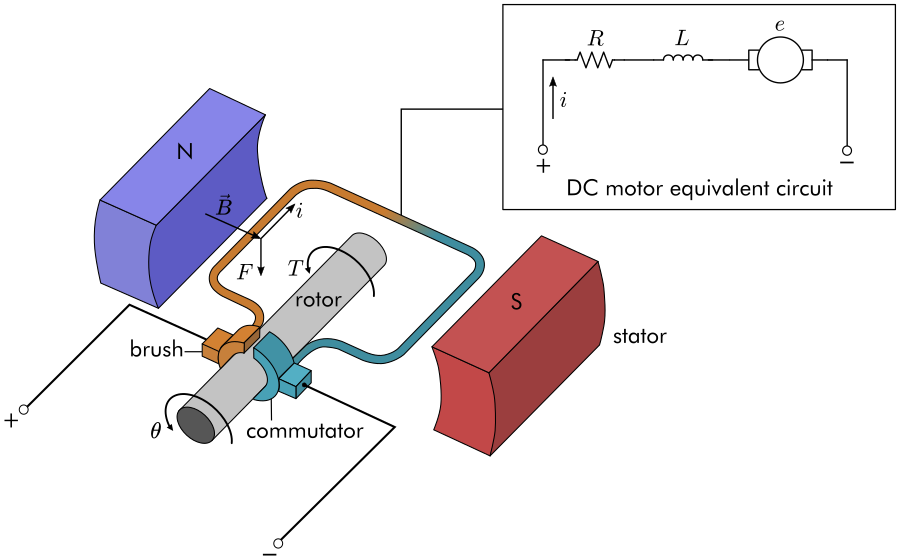

*DC motor schematic. A net torque *$T$ *is generated on the armature by Lorentz forces. In the electrical domain, the motor is represented by a series of three circuit elements.*

**Derivation of the DC motor differential equations**

Under typical operating conditions, the torque generated by a DC motor is directly proportional to the current passing through it:

        
$$T = k_mi$$


where $k_m$ is a proportionality constant determined by the characteristics of the specific motor. This relationship fails for large values of $i$. 

When the armature rotates, it generates a back electromotive force ([back EMF](https://en.wikipedia.org/wiki/Counter-electromotive_force)) that opposes the applied voltage. In the circuit diagram, this is represented by a motor symbol. The voltage drop due to the back EMF, denoted $e$, is proportional to the rotational velocity of the armature:

        
$$e =k_e \dot{\theta}$$


where $k_e$ is a constant of proportionality. To derive the relationship between the current $i$ and the motor shaft angular position $\theta$, you can apply Kirchhoff's voltage law and Newton's second law in terms of torques acting on the motor shaft. Kirchhoff's voltage law implies that the sum of the voltage drops across the circuit must equal the applied voltage:

        
$$iR + L \frac{di}{dt} + k_e \dot{\theta} = v$$
         
$$(1)$$


where $v$ is the electric potential applied to the motor. In the absence of other applied torques, the equation of motion can be derived by balancing the inertia of the motor shaft ($J \ddot{\theta}$) with the applied torque ($T$) and frictional resistance ($B \dot{\theta}$).

        
$$J \ddot{\theta}  = T - B \dot{\theta}$$


Using the linear relationship between torque and current, this is equivalent to:

        
$$J \ddot{\theta} + B \dot{\theta}  = k_m i$$
                 
$$(2)$$


 **Exercise. **In this exercise, you will compute transfer functions of the DC motor system. Assume that the system starts at rest ($i = i' = \theta = \dot{\theta} = 0$). Also, assume that the applied voltage is a function of time $v = v(t)$.

**(a)** Compute the Laplace transform of the voltage conservation equation (1) and apply the initial conditions. Type your result below in terms of the defined symbolic variables. 

  **Pro-tip**: When you write a symbolic equation, you assign the whole equation to a MATLAB variable using the assignment operator "$=$" (single equals). The equals sign in the symbolic equation is written using "`=="` (double equals). For example: 

% Use these symbolic variables
syms L R k_e J B k_m    % Constants
syms Theta I s V        % Laplace domain variables
% Write your laplace transform equation here
eqn1 = NaN;

checkEqn1(eqn1)

**(b) **Compute the Laplace transform of the equation of motion (2) and apply the initial conditions. Type your answer below in terms of the defined symbolic variables. 

% Write your laplace transform equation here
eqn2 = NaN;

checkEqn2(eqn2)

**(c) **Solve for the angular displacement transfer function $G(s) = \frac{ \Theta(s) }{V(s)}$ using your results from **(a)** and **(b)**.

% Write your transfer function here
ThetaOverV = NaN;

checkThetaOverV(ThetaOverV)

**(d)** Solve for the angular velocity transfer function $H(s) = \frac{\Omega(s)}{V(s)}$ where $\Omega$ is the Laplace transform of the angular velocity $\omega(t) = \dot{\theta}(t)$.

% Write your transfer function here
OmegaOverV = NaN;

checkOmegaOverV(OmegaOverV)

## Pole analysis

You can gain insight into the characteristics of a dynamic system without actually solving it by analyzing the form of its transfer function. The poles of the transfer function offer the most insight.

**Definition. **The **poles** of a rational transfer function occur where the denominator is zero. Consider a rational transfer function in factored form:

    
$$G(s) = K \frac{ (s-z_1)(s-z_2) \ldots (s-z_m) }{ (s-p_1)(s-p_2) \ldots (s-p_n)}$$


The poles are $p_1$, $p_2$, $\ldots$, $p_n$.

### Stability

The real parts of the poles determine the stability of the system.

- A pole with a positive real part ($\text{Re}(p_i) > 0$) characterizes an exponential growth component of the solution. 

- A pole with a negative real part ($\text{Re}(p_i) < 0$) characterizes an exponential decay component of the solution.

- A pole with a zero real part ($\text{Re}(p_i) = 0$) characterizes a steady component of the solution. 

Poles with an imaginary component ($\text{Im}(p_i) \neq 0$) generate oscillatory behavior. Such poles necessarily come in conjugate pairs (so that their product is real). 

 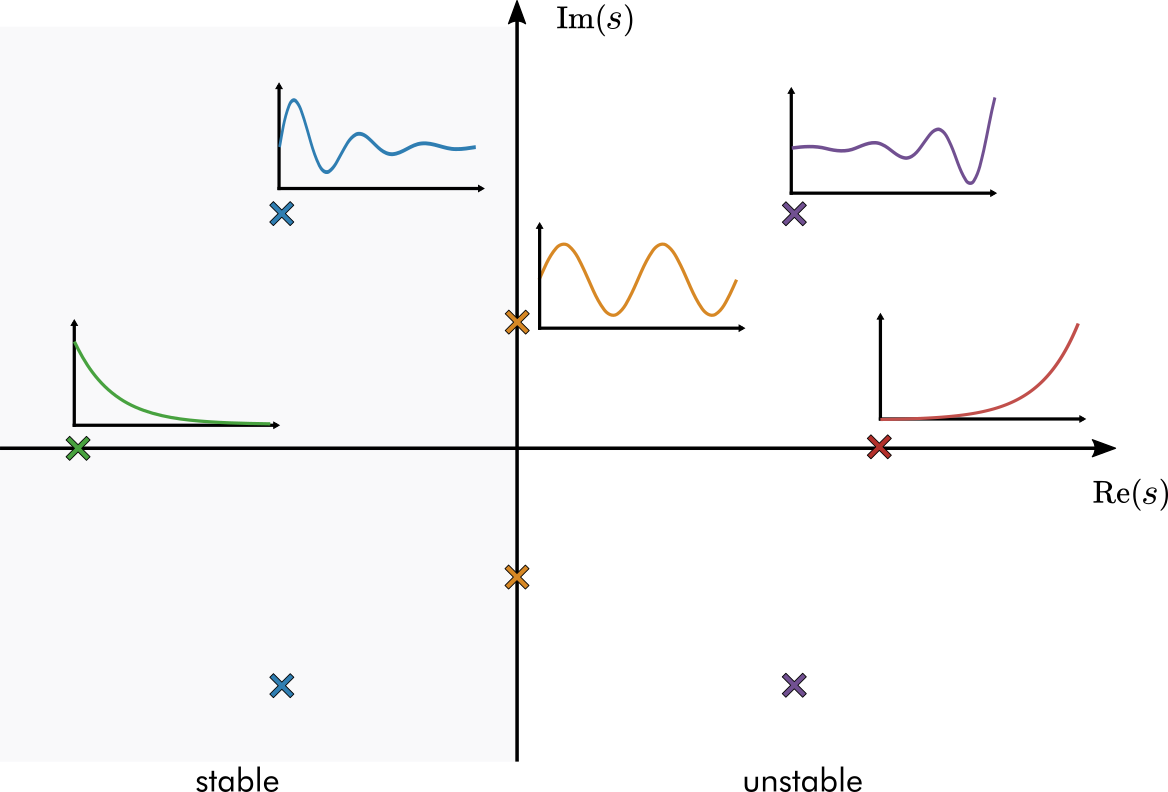

* Impulse responses characterized by the position of poles in the complex *$s$*-plane. Poles in the left-half plane (where *$\text{Re}(p) < 0$*) are stable. The poles in the bottom-half plane are the conjugate poles required for the imaginary poles.*

   **Activity. **In this activity, you will visually explore the relationship between transfer function poles and time-domain responses.

**Part 1**. Use the app

- Begin the activity by running the attached app: [polesApp.mlapp](matlab: run polesApp). Note that this link will only work if `polesApp.mlapp` is in the current folder or on the MATLAB Search Path.

- Show the impulse response of the default system by clicking the *compute response* button.

- Click and drag the poles to different locations in the $s$-plane and recompute the response.

**Part 2.** Transfer function poles

- You can change the transfer function by adjusting the number and location of the poles and zeros. Set the number of poles to two and change the location of the poles to $p = -1, -2$. The transfer function should be $F(s) = 1/[(s+1)(s+2)]$. Is the system stable or unstable?

- Adjust the number of poles and their locations to reproduce the transfer functions shown below.

**            a. **$F(s) = \frac{1}{s^2 + 1}$**            b. **$F(s) = \frac{1}{(s-1)(s^2+2s+2)}$**            c.  **$F(s) = \frac{1}{(s-1)(s+2)(s^2+4s+8)}$

         3.  Which of the transfer functions are stable? Which are unstable?

**Part 3. **Single pole system responses

- Change the number of poles (/pole pairs) to 1. Also, adjust the stop time of the response simulation to ~20 seconds using the slider.

- Adjust the position of the pole (or pole pair, when the pole is complex) to produce graphs similar to the various impulse responses shown below. 

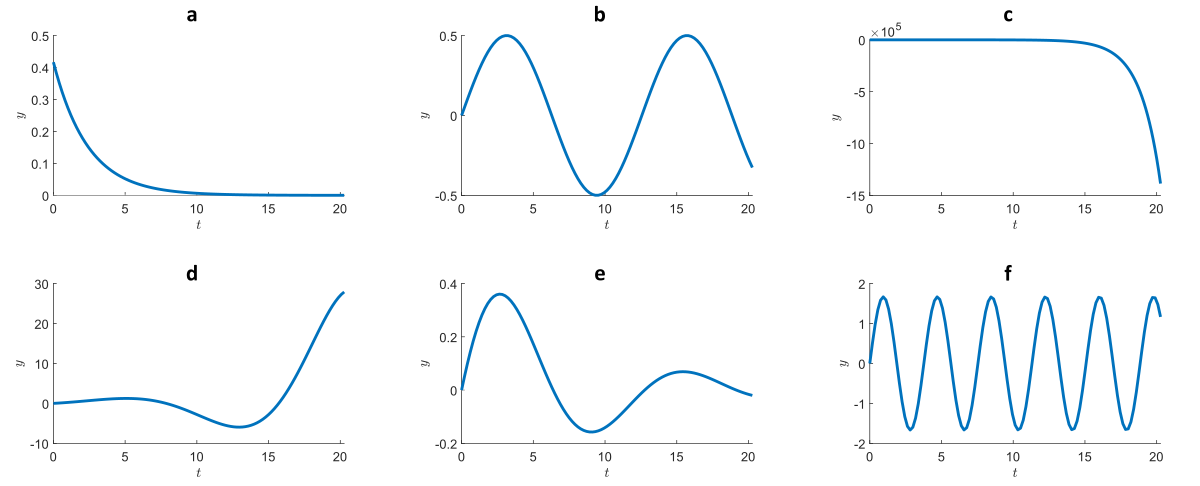

showAnswers = false; % Click the checkbox to show the answers
showSinglePoleAnswers(showAnswers)

**Part 4. **Two pole system responses

- Change the number of poles (/pole pairs) to 2. Continue to observe the impulse responses with a final time of 20 seconds.

- Adjust the pole positions to reproduce the behaviors shown in the plots below.

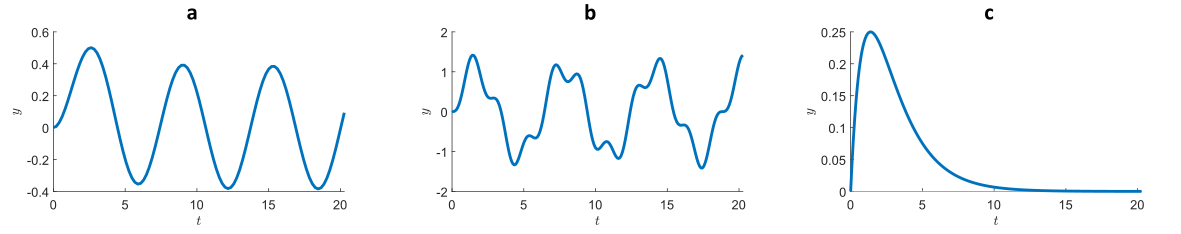

showAnswers = false; % Click the checkbox to show the answers
showDoublePoleAnswers(showAnswers)

**  Reflect.** 

- What effect does increasing the magnitude of the imaginary component of a pole have? 

- What effect does increasing the magnitude of the real component of a pole have?

- In a system with one stable pole and one unstable pole, is it possible for a stable pole to "balance out" an unstable pole, leading to an overall stable system?

 **Exercise. **You can write the DC motor angular velocity transfer function as

        
$$\frac{\Omega}{V} = \frac{g}{ s^2 + bs + c}$$


(a) Suppose that a DC motor has constants $g =60$, $b = 2.3$, and $c = 11$. Define the transfer function in MATLAB using the [`tf`](https://www.mathworks.com/help/control/ref/tf.html) function. 

% Write your code here


(b) Is the system stable? You can plot the poles in the $s$-plane using the [`pzmap`](https://www.mathworks.com/help/control/ref/lti.pzmap.html) function. For example, to plot the poles of a transfer function `G,` use:

% Write your code here


(c) What are the poles of the transfer function? You can use the [`pole`](https://www.mathworks.com/help/control/ref/lti.pole.html) function to compute the poles of a dynamic system in MATLAB. For example, to identify the poles of a transfer function R, use:

% Write your code here


**  Reflect.** 

- What response would you expect for a brief (impulse) applied voltage in a physical DC motor?

- Based on the poles identified in this exercise, what impulse response do you expect?

- Does the behavior suggested by the poles match your intuition for a physical DC motor? Does the pole analysis suggest any unexpected behaviors?

### Natural frequency

The locations of the poles in the $s$-plane determine the natural oscillation frequencies present in the system.

- The natural (undamped) frequency (in rad/s) contributed by a pole $p$ is the pole magnitude, $r = |p|$. 

- The phase, $\phi = \arg p$, determines the relative strength of the oscillatory component.

            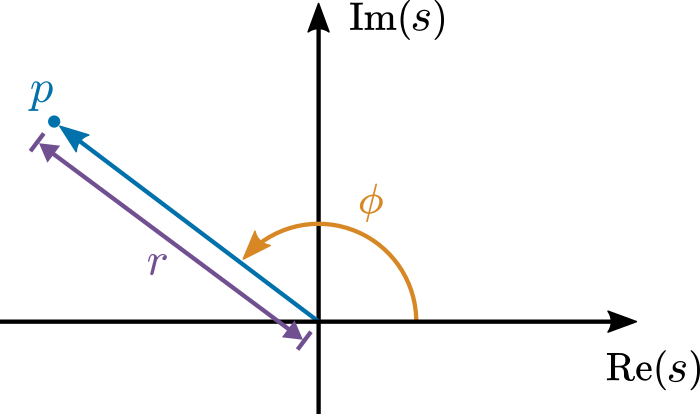

*        Phase *$\phi$* and magnitude *$r$* of pole *$p$* shown in the complex plane*

   **Activity. **In this activity, you will explore how poles relate to the natural frequency response.

Consider the transfer function:

    $H(s) = \frac{1}{s^2 -2\,\mathrm{cos}\left(\phi \right)\,r\,s+r^2}$,  which is constructed with poles: $p = r(\cos \phi \pm i\sin \phi)$.

- The transfer function poles are plotted below. Change the slider values to $(r,\phi) =$ $(1,135^\circ)$. Are oscillations present in the impulse response?

- Set $(r,\phi) =$ $(1,100^\circ)$ and then $(r,\phi) =$ $(1,90^\circ)$. Does the frequency of the oscillation change? Are the oscillations more prominent?

- Set $(r,\phi) =$ $(1.5,90^\circ)$ and then $(r,\phi) =$ $(2,90^\circ)$. Does the frequency of the oscillation change? Are the oscillations more prominent?

r = 1;        % Default: 1
phiDeg = 45;     % Default: 45
plotPoles(r,phiDeg) % Plot the poles using a helper function 

**  Reflect.** 

- Does the conjugate pole $p = r(\cos \phi - i\sin \phi)$ contribute a different natural frequency than the first pole $p = r(\cos \phi + i\sin \phi)$? Why or why not?

- As $r$ increases, does the frequency increase or decrease?

- As $\phi$ approaches $180^\circ$, does the oscillation become more or less prominent?

 **Exercise.** A specific example of the DC motor angular velocity transfer function is

G = tf([0 0 60],[1 2.3 11])

**(a)** Compute the poles of the system and then use the poles to compute the system's natural frequencies in rad/s.

% Write your code here


**(b)** You can also use the [`damp`](https://www.mathworks.com/help/control/ref/lti.damp.html) function to analyze the natural frequencies of the system. Validate your solution in **(a)** by calling the `damp` function.

% Write your code here


**  Reflect.** 

- What physical interactions cause the oscillatory behavior in the DC motor system?

- The damp function offers an additional output: damping. What does this value represent?

### Analysis of a second-order system

Second-order systems with a pair of conjugate poles and no zeros are useful for illustrating the natural frequency response analytically. It is helpful to write this type of system in the form:

        
$$G(s) = \frac{ K }{s^2 + 2 \zeta \omega_n s  + \omega_n^2$$


where 

- $K$ is the gain coefficient

- $\zeta$ is the damping ratio

-  and $\omega_n$ is the (undamped) natural frequency. 

These parameters are helpful for drawing a connection between the natural response of the system and the properties of the poles. In this section, the poles of the second-order system will be analytically computed and related to the natural response of the system.

**Pole analysis**

The poles of the system occur when the denominator is zero:

    
$$p = - \zeta \omega_n \pm \omega_n \sqrt{\zeta^2 - 1 }$$


For simplicity, consider $\zeta \in [0,1)$. In this case, the poles are

    
$$p = - \zeta \omega_n \pm i \omega_n \sqrt{1 - \zeta^2}$$


As stated above, the natural frequency is defined as the magnitude of the pole. The magnitude is computed as $\sqrt{ Re^2 + Im^2}$:

    
$$\begin{array}{rl} |p|
 &= \sqrt{ (-\zeta \omega_n)^2 + ( \pm \omega_n \sqrt{1-\zeta^2})^2 } \\ 
 &= \sqrt{ \zeta^2 \omega_n^2 + \omega_n^2 (1-\zeta^2) } \\ 
 &= |\omega_n|\ 
\end{array}$$


This illustrates why this form of the equation is used: the natural frequency is the parameter $\omega_n$. 

The damping ratio $\zeta$ determines the relative strength of the exponential part of the response. As $\zeta \rightarrow 1$, the complex part of the pole tends to zero, implying less oscillatory and stronger exponential behavior. For stable systems, that implies greater damping. The gain coefficient $K$ affects the magnitude of the response, not the time-dependent behavior.

**Natural response**

The impulse response is also called the natural response. The natural response $x(t)$ is computed by taking the inverse Laplace transform of

        
$$\frac{X(s)}{U(s)} = \frac{X(s)}{1} = \frac{ K }{s^2 + 2 \zeta \omega_n s  + \omega_n^2$$


because the impulse $u(t) = \delta(t)$ has a Laplace transform $U(s) = 1$. You can find the response's analytic form by referring to a table or using the [`ilaplace`](https://www.mathworks.com/help/symbolic/sym.ilaplace.html) function.

syms s zeta omega_n K X(s) x(t)
X(s) = K/(s^2 + 2*zeta*omega_n*s + omega_n^2) 
x(t) = ilaplace(X) % The impulse response in the time domain

Notice that the impulse response is a product of an exponential and sine function. From these functions observe that:

- The sine function frequency (in rads/s) is $\omega_n \sqrt{1-\zeta^2}$. If the damping $\zeta = 0$, then the frequency is $\omega_n$. This is the reason $\omega_n$ is often referred to as the *undamped *natural frequency.

- The rate of decay of the exponential damping function is $\omega_n \zeta$. 

- The gain parameter $K$ only contributes as a constant multiplier to the magnitude of the response.

   **Activity. **Adjust the sliders to view different time-domain responses for the classical second-order system:

    
$$G(s) = \frac{ K }{s^2 + 2 \zeta \omega_n s  + \omega_n^2$$


K = 3;
zeta = 0.2;
omega_n = 2;

plotNaturalResponse(zeta,omega_n,K) % Helper function that plots the response for the second order system

**  Reflect.** 

- Does the carrier frequency of the solution change with the damping coefficient $\zeta$?

- Does the exponential envelope change with $\omega_n$?

- How does the gain $K$ affect the response?

 **Exercise.**  Mass-spring-damper analysis

You can analyze a mass-spring-damper by looking at the poles of its transfer function.

      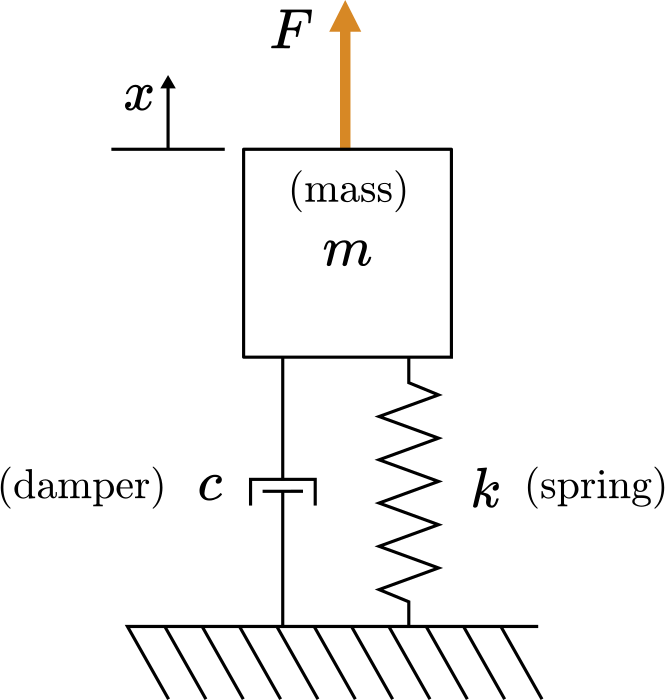

        *Mass-spring-damper diagram*

Consider a mass-spring-damper that

- is dynamically forced by an arbitrary function $u(t)$

- has zero initial conditions: $x(0) = 0$ and $x'(0)=0$

The position transfer function is

    
$$G(s) = \frac{X(s)}{U(s)} = \frac{1}{ m s^2 + cs + k}$$


**(a) **Write the mass-spring-damper transfer function in the form 

         
$$G(s) = \frac{ K }{s^2 + 2 \zeta \omega_n s  + \omega_n^2$$


and solve for the expressions of the gain $K$, damping ratio $\zeta$, and natural frequency $\omega_n$ in terms of the mass-spring-damper parameters. Write your answers using the symbolic variables $c$, $m$, and $k$.

% Use these symbolic variables
syms m c k
% Replace the NaNs with your expressions
K = NaN;
omega_n = NaN;
zeta = NaN;

checkMSDExpressions(K,omega_n,zeta) % Checks your answers

**(b)  **Solve for the symbolic expressions of the poles of $G$ in terms of the mass-spring-damper parameters $m$, $c$, and $k$. Store the expressions below in `pplus` and `pminus` where `pplus` stores the positive root.

% Write your answers here
poles = NaN;
pplus = NaN;
pminus = NaN;

checkMSDPoles(pplus,pminus) % Checks the answers

**(c) **You can gain insight into the dynamics of the system by examining how the poles change in the $s$-plane when parameters are varied. 

- The graph below shows the pole locations under variations of a parameter starting with $k = m = 1$ and $c = 0$.

- Adjust the dropdown to change which parameter is varied. 

- The curves plot the pole locations between the specified parameter's starting value and maximum value. Try changing the dropdown and the `maxValue` to observe changes to the poles.

- Use the plot to answer the reflection questions.

variation = "m";
maxValue = 2;

plotPoleVariation(variation,maxValue) % Helper function to generate the plot

**  Reflect.** 

- What happens to the poles when $c = 2$? Physically, what does this represent?

- If any of the parameters are (individually) negative, what happens to the poles? What are the physical implications of negative parameters?

- As $k$ is increased, what happens to the poles? How does this relate to the natural frequency expression that you solved for in part **(a)** ($\omega_n = \sqrt{k/m}$)?

## Zero analysis

The analysis of zeros is less straight-forward than the analysis of the poles of the system, because their effects are less pronounced. Zeros contribute to

- the transient behavior of the response,

- the magnitude of the response, and

- the response to different input frequencies.

   **Activity.** Consider the simple system:

    
$$G(s) = \frac{ s-z_0}{s+1}$$


Adjust the location of the zero using the slider and observe the changes to the response.

z0 = 0; % Position of the zero
G = tf([1 -z0],[1 1]);           % The transfer function G(s)
axlim1 = [-3 3 -3 3];            % Axis limits for the first graph
axlim2 = [0 10 -5 5];            % Axis limits for the second graph
pzmapAndImpulse(G,axlim1,axlim2) % Generates the plot

**  Reflect.** 

- Is the stability or long-term behavior of the system affected by the zero location?

- How is the transient response affected by the zero?

- Does the system become unstable when the zero is in the right-half plane?

- What happens as the zero approaches the pole?

   **Activity. **In this activity, you will visually explore the relationship between transfer function zeros and time-domain responses. You will inspect the step responses of

        
$$G = \frac{s-z_0}{s^2 + 2s + 2}$$


- Begin the activity by running the attached app, [polesApp.mlapp](matlab: run polesApp). Note that this link will only work if `polesApp.mlapp` is in the current folder or on the MATLAB Search Path. 

- Set the number of poles/pole pairs to 1

- Place the pole pair at $p = -1 \pm i$.

- View the **step** response by selecting *Step *in the *Response type *menu.

- Add a zero to the plot. Adjust the position of the zero to generate the step responses shown below.

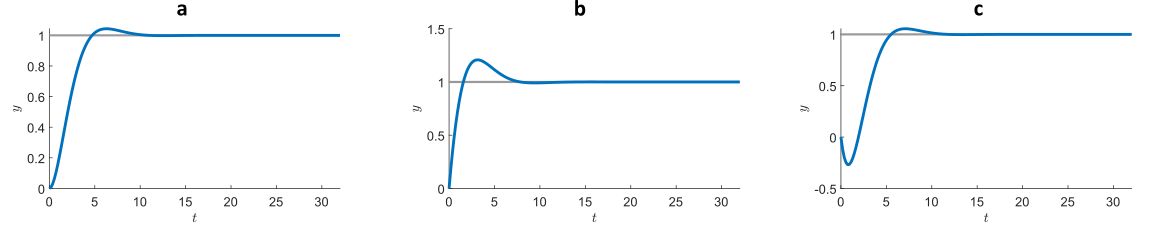

showAnswers = false;
showZeroPart1Answers(showAnswers)

**  Reflect.** 

- The transient of the step response that exceeds the steady value ($y = 1$, in this case) is known as the **overshoot**. As the zero moves further in the negative direction along the real axis, what happens to the overshoot?

- The time it takes to reach the steady value ($y = 1$, in this case) is known as the **rise time**. How is the rise time affected by changes to the zero, $z_0$?

- Try other values of the poles and zero, do you observe similar changes to the overshoot and rise time?

 **Exercise.**  In this exercise, you will examine the changes to the analytic step response of a transfer function with a single zero.

Consider the transfer function used in the previous activity:

    
$$G = \frac{s-z_0}{s^2 + 2s + 2}$$


**(a) **Compute the symbolic form of the **step** response of the transfer function, $x(t)$. You can perform the analytic computations by hand or using the Symbolic Math Toolbox. 

% Use these symbolic variables
syms s z_0 t positive 
% Write your solution here
x = NaN

**(b) **Plot the analytic step response with $z_0 = -1$ on the interval $t \in [0, 10]$. If you computed the step response function with the Symbolic Math Toolbox, you can use the [`matlabFunction`](https://www.mathworks.com/help/symbolic/matlabfunction.html) command to convert it to a function handle that you can evaluate.

% Create your plot here


**(c) **Using the analytic form of the transfer function, compute the limit of the function as $t \to \infty$.

% Write your solution here
tlim = NaN

**  Reflect.** 

- Vary the location of the zero ($z_0$) and observe how the step response changes.

- How does the location of the zero ($z_0$) affect the overall magnitude of the step response? Where does this show up in the analytic solution?

- How does the location of the zero ($z_0$) affect the rise time and overshoot? Where does this show up in the analytic solution?

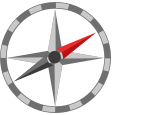**Further exploration**

- You can interactively explore transfer functions, their poles, time-domain response, and more using the [Control System Designer](https://www.mathworks.com/help/control/ref/controlsystemdesigner-app.html) app.

**Helper functions**

**Plots**

function plotPoleVariation(variation,maxValue)
% Plots the poles of a specific transfer function under variations of the
% specified parameter
    
    % Create transfer function
    k = 1;
    m = 1;
    c = 0;
    H = tf([0 0 1],[1 0 1]);
    
    % Compute pole trajectories
    if(variation == "k")
        k = linspace(k,maxValue,400);
    elseif(variation =="m")
        m = linspace(m,maxValue,400);
    elseif(variation =="c")
        c = linspace(c,maxValue,400);
    end
    p1 = -(c - sqrt(c.^2 - 4*k*m))./(2*m);
    p2 = -(c + sqrt(c.^2 - 4*k*m))./(2*m);    
    
    % Create plot
    figure("Position",[0 0 650 600])
    pzmap(H,"b")
    grid on
    axis([-5 5 -5 5])
    hold on
    plot(real(p1),imag(p1),"b")
    plot(real(p2),imag(p2),"b")
    plot(real(p1(end)),imag(p1(end)),"b.","markersize",8)
    plot(real(p2(end)),imag(p2(end)),"b.","markersize",8)
    text(real(p1(end)),imag(p1(end)),"  " +variation+ "_m_a_x = " + num2str(maxValue))
    text(real(p2(end)),imag(p2(end)),"  " +variation+ "_m_a_x = " + num2str(maxValue))
    hold off
    axis equal
end

function plotNaturalResponse(zeta,omega_n,K)
% Plots the natural frequency response
    b = 2*zeta*omega_n;
    c = omega_n^2;
    H = tf([0 0 K],[1 b c]);
    
    syms s X x t
    X = K/(s^2 + b*s + c);
    x = ilaplace(X);
    envelope = K*exp(-omega_n*t*zeta)/(omega_n*sqrt(1-zeta^2));
    
    % Plot the poles and impulse response
    figure("Position",[0 0 1600 450])

    subplot(1,3,1)
    pzmap(H,"b")
    grid on
    axis equal
    lineObjs = findobj(gca,"Type","Line");   
    axis([-10 10 -10 10])
    set(lineObjs(3),"MarkerSize",10,"LineWidth",2,"Color",[0.8500 0.3250 0.0980]);           
    
    subplot(1,3,2)
    [y,t] = impulse(H,10);
    ev = K*exp(-omega_n*zeta*t)/(omega_n*sqrt(1-zeta^2));
    plot(t,y)
    hold on
    plot(t,ev,"Color",[0.8500 0.3250 0.0980])
    plot(t,-ev,"Color",[0.8500 0.3250 0.0980])
    hold off
    xlabel('$t$',"Interpreter","latex")
    ylabel('$x$',"Interpreter","latex")
    
    subplot(1,3,3)
    axis([-0.1 1 0 1])
    text(0,0.75,"$X(s) = " +latex(X)+"$","Interpreter","latex","FontSize",20)
    text(0,0.5,"$x(t) = " +latex(x)+"$","Interpreter","latex","FontSize",20,"Color",[0 0.4470 0.7410])
    if(zeta < 1)
        text(0,0.25,"envelope = $" +latex(envelope)+"$","Interpreter","latex","FontSize",20,"Color",[0.8500 0.3250 0.0980])
    end
    axis off 
   

end

function plotPoles(r,phiDeg)
% Plots the poles and impulse response of the specific transfer function
% defined below
    % The transfer function:
    b = -2*cosd(phiDeg)*r;
    c = r^2;
    H = tf([0 0 1],[1 b c]);
    H % Display H
    disp("poles: " + num2str(r*cosd(phiDeg),3) + " ± " + num2str(r*sind(phiDeg),3) + "i" )
    
    % Plot the poles using pzmap
    figure("Position",[0 0 1200 500])
    subplot(1,2,1)
    pzmap(H,"b")
    grid on
    axis([-3 3 -3 3])
    axis equal
    lineObjs = findobj(gca,"Type","Line");   
    set(lineObjs(3),"MarkerSize",10,"LineWidth",2,"Color",[0.8500 0.3250 0.0980]);           
    
    % Impulse response plot
    subplot(1,2,2)
    impulse(H,20)   
end


function pzmapAndImpulse(G,axlim1,axlim2)
% Plots the poles and impulse response together
    figure("Position",[0 0 1200 500])    
    
    % Pole-zero map plot
    subplot(1,2,1)
    pzmap(G,"b")
    grid on
    axis(axlim1)
    axis equal
    syms s
    Htex = newline + "\ " + newline + "$G = " + latex(poly2sym(G.num{1},s)/poly2sym(G.denom{1},s)) + "$ \quad";
    text(axlim1(2),axlim1(4),Htex,"Interpreter","Latex","HorizontalAlignment","right",...
        "FontSize",18,"VerticalAlignment","top")
    lineObjs = findobj(gca,"Type","Line");   
    set(lineObjs(3),"MarkerSize",10,"LineWidth",2,"Color",[0.8500 0.3250 0.0980]);           
    set(lineObjs(2),"MarkerSize",7,"LineWidth",1.5,"Color",[0 0.4470 0.7410]);   
    
    % Impulse-response plot
    subplot(1,2,2)
    impulse(G,10) 
    axis(axlim2)
    ylabel("x")
end


**Checks**

function isEqualCheck(userSubmission,correctAnswer)
% This function checks if two results are equal and displays feedback
    if( isequal(userSubmission, correctAnswer) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
    end
end

function isEqualCheckSimplify(userSubmission,correctAnswer)
    isEqualCheck(simplify(sym(userSubmission)), simplify(sym(correctAnswer)))
end

function checkEqn1(userSubmission)
    syms L R k_e    
    syms Theta I s V 
    eqn = R*I + L*s*I + s*k_e*Theta == V;
    isEqualCheckSimplify(userSubmission,eqn);
end

function checkEqn2(userSubmission)
    syms L R k_e J B k_m  
    syms Theta I s V 
    eqn = J*s^2*Theta + B*s*Theta == k_m*I;
    isEqualCheckSimplify(userSubmission,eqn);
end

function checkThetaOverV(userSubmission)
    syms L R k_e J B k_m  
    syms Theta I s V 
    ThetaOverV = k_m/(s*(L*J*s^2 + (R*J+L*B)*s + B*R + k_m*k_e));
    isEqualCheckSimplify(userSubmission,ThetaOverV);
end

function checkOmegaOverV(userSubmission)
    syms L R k_e J B k_m  
    syms Theta I s V 
    soln = k_m/(L*J*s^2 + (R*J+L*B)*s + B*R + k_m*k_e);
    isEqualCheckSimplify(userSubmission,soln);
end

function showSinglePoleAnswers(showAnswer)
    if(showAnswer)
        disp("Poles used to generate the plots: " + newline +...
                "a: -2.5,  b: ±2i,  c: 1.4,  d: 1±2i,  e: -4±2i,  f: ±0.6i")
    end
end

function showDoublePoleAnswers(showAnswer)
    if(showAnswer)
        disp("Poles used to generate the plots: " + newline +...
                "a: -2.5,±i,  b: ±i,±0.3i,  c:-1,-2")
    end
end

function showZeroPart1Answers(showAnswer)
    if(showAnswer)
        disp("Zeros used to generate the plots: " + newline +...
                "a: 0,  b: -2,  c: 1.5")
    end
end

function checkMSDExpressions(K_user,omega_n_user,zeta_user)
    syms m c k;
    K = 1/m;
    omega_n = sqrt(k/m);
    zeta = c/(2*sqrt(m*k));
    disp("K:")
    isEqualCheckSimplify(K,K_user)
    disp(newline+ "omega_n:")
    isEqualCheckSimplify(omega_n,omega_n_user)
    disp(newline+ "zeta:")
    isEqualCheckSimplify(zeta,zeta_user)
end

function checkMSDPoles(pplusUser,pminusUser)
    syms c k m
    pplus = -(c - sqrt(c^2 - 4*k*m))/(2*m);
    pminus =  -(c + sqrt(c^2 - 4*k*m))/(2*m);
    disp("pplus:")
    isEqualCheckSimplify(pplus,pplusUser)
    disp(newline+ "pminus:")
    isEqualCheckSimplify(pminus,pminusUser)
end

% Suppress unused suggestions
%#ok<*UNRCH> 
%#ok<*NODEF> 